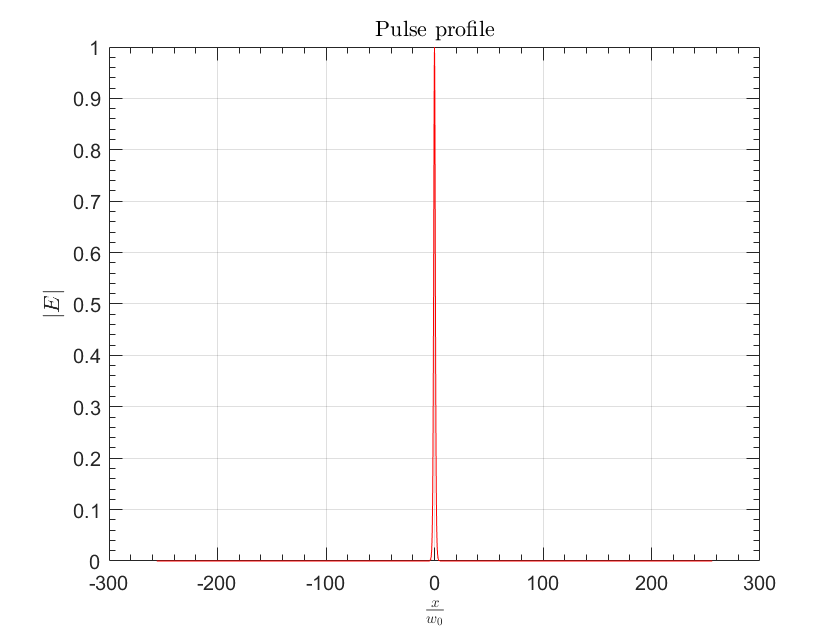

% Solves normalized NLS equation with split-step method
% Modifed Raman response function (2006 OL paper) 
clc
clear
clf

%---Specify input parameters
T0 = 50;          % pulse width in fs
lam0 = 835;       % in nm
s = lam0/(2*pi*3e2*T0);  % self-steepening

distance = 1;   % normalized to dispersion length
N = 5;          % soliton order
sbeta2 = -1;    % sign of beta_2
mshape = 0;     % 0 for sech, m>0 for super-Gaussian
delta3= 0.05;   % beta3/(6*T0*abs(beta2))
delta4 = 0.0;   % beta4/(24*T0^2*abs(beta2))
%delta5=0; delta6=0; delta7=0; delta8=0;
chirp0 = 0;     % input pulse chirp (default value)

%---set simulation parameters
nt = 2^15;
Tmax = 256;       % FFT points and window size
step_num = 500;   %round(40*distance*N^2); 
zstep = 100;      % no of z steps
ng = step_num/zstep;        % store data for 3D.
deltaz = distance/step_num; % step size in z
dtau = (2*Tmax)/nt;         % step size in tau 

%-------tau and omega arrays
tau = (-nt/2:nt/2-1)*dtau;  % temporal grid
omega = fftshift((pi/Tmax)*(-nt/2:nt/2-1));  % freq array

% Defination of Raman response function
fR = 0.245;  fb=0.21;
tau1=12.2/T0; tau2=32/T0; tau_b=96/T0;
h = (1-fb)*(tau1^2 + tau2^2)/(tau1*tau2^2)*exp(-tau/tau2).*sin(tau/tau1)...
        +fb*((2*tau_b-tau)/tau_b^2).*exp(-tau/tau_b);
h(1:nt/2) = 0;      % causality

%---Input Field profile
if mshape==0
    uu = sech(tau).*exp(-1i*chirp0*tau.^2);     %soliton
else
    uu = exp(-0.5*(1+1i*chirp0).*tau.^(2*mshape)); %super-Gaussian
end
figure();
plot(tau,abs(uu).^2, "Color", [1 0 0])
title('Pulse profile', "Interpreter", "latex"); 
xlabel('$\frac{x}{w_0}$', "Interpreter", "latex"); 
ylabel('$|E|$', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
   
%-----Input 3D data   
  uu_3d(1,:)=uu.*conj(uu); % Intensity in time domain
  temp = fftshift(ifft(uu));
  spect_3d(1,:)=abs(temp).^2; % spectrum au unit

%----store dispersive phase shifts to speedup code
dispersion = exp(1i*deltaz*(0.5*sbeta2*omega.^2 +...
    delta3*omega.^3 + delta4*omega.^4));
hhz = 1i*N^2*deltaz;
  
%*********[ Beginning of MAIN Loop]***********
% scheme: 1/2N -> D -> 1/2N; first half step nonlinear
temp = uu.*exp(abs(uu).^2.*hhz/2);    % note hhz/2
for n=1:step_num
  f_temp = ifft(temp).*dispersion;    
  uu = fft(f_temp); 
  sst1=deriv1(abs(uu).^2,dtau);
  sst2=deriv1(uu,dtau);
  sst=1i*(1-fR)*s*(sst1 + conj(uu).*sst2);
  
  P=uu.*conj(uu);
  convl=(nt*dtau)*fft(ifft(h).*ifft(P));
  convl=fftshift(convl);
  sst3=deriv1(convl,dtau);
  sstnew=1i*s*fR*(sst3 + (conj(uu).*convl)./(P+eps).*sst2);
  temp = uu.*exp(((1-fR)*(abs(uu).^2)+ sst+ fR*convl+ sstnew).*hhz);
  spect=fftshift(ifft(temp));
        if mod(n,ng)==0
          uu_3d((n/ng+1),:)=temp.*conj(temp); % temporal power
          spect_3d((n/ng+1),:)=spect.*conj(spect); % spectral power
        end
end
%***************[ End of MAIN Loop ]**************

%----Plot output pulse shape and spectrum 
colormap(slanCM('magma'))

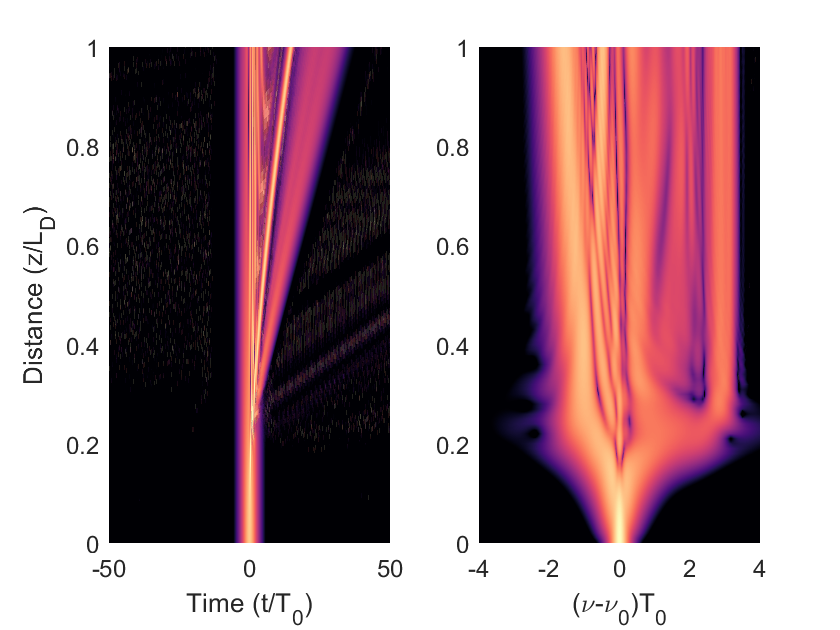

z=linspace(0,distance,zstep+1); % normalised distance
subplot(1,2,1);
    uu_3d = 10*log10(uu_3d); % convert to dB units
    pmax = max(max(uu_3d));       % maximum value
    pcolor(tau,z,uu_3d);          % 3D plot
    caxis([pmax-50, pmax]); xlim([-50,50]); shading interp;
    set(gca,'FontSize', 12); %title('(a)')
    xlabel('Time (t/T_0)'); ylabel('Distance (z/L_D)')

subplot(1,2,2)
    spect_3d=10*log10(spect_3d); % convert to dB units
    freq = fftshift(omega/(2*pi)); % freq array
    pmax = max(max(spect_3d)); % max value for scaling plot
    pcolor(freq,z,spect_3d);
    caxis([pmax-50, pmax]); xlim([-4,4]); shading interp;
    set(gca,'FontSize', 12); %title('(a)')
    xlabel('(\nu-\nu_0)T_0'); %ylabel('Distance (z/L_D)')


%Plot Spectogram
% temp = fftshift(omega)/(2*pi);  %store frequecnies
% sample=4; gate_w=1;
% spxf = xfrog(gate_w,sample,tau,uu);
% figure(9);
% pcolor(tau(1:sample:nt),temp(1:sample:nt), 10*log10(spxf+1e-5)');
% shading interp;